clc;
clear;
syms a b t c real

A=1

A = 1

B=0.5

B = 0.5000

C=2

C = 2

%jounce
jounce1=a*sin((1/b)*pi*t)

$$jounce1 = a\,\sin\left(\frac{\pi \,t}{b}\right)$$

jounce2=-a*sin(1/(2*b)*pi*t-pi/2)

$$jounce2 = a\,\sin\left(\frac{\pi }{2}-\frac{\pi \,t}{2\,b}\right)$$

jounce3=a*sin((1/b)*pi*t-3*pi)

$$jounce3 = -a\,\sin\left(\frac{\pi \,t}{b}\right)$$


jounce3_c0=eval(simplify(subs(jounce3,[a,b,t],[A,B,4*B])))

jounce3_c0 = 0

%jerk

jerk1=simplify(int(jounce1,t)+c);
jerk1=Csolve(jerk1,a,b,t,c, A,B,0,0)

$$jerk1 = \frac{5734161139222659}{36028797018963968}-\frac{a\,b\,\cos\left(\frac{\pi \,t}{b}\right)}{\pi }$$


strt2=eval(simplify(subs(jerk1,[a,b,t],[A,B,B])));

jerk2=simplify(int(jounce2,t)+c);
jerk2=Csolve(jerk2,a,b,t,c, A,B,B,strt2)

$$jerk2 = \frac{2\,a\,b\,\sin\left(\frac{\pi \,t}{2\,b}\right)}{\pi }$$


strt3=eval(simplify(subs(jerk2,[a,b,t],[A,B,3*B])))

strt3 = -0.3183


jerk3=simplify(int(jounce3,t)+c);
jerk3=Csolve(jerk3,a,b,t,c, A,B,3*B,strt3)

$$jerk3 = \frac{a\,b\,\cos\left(\frac{\pi \,t}{b}\right)}{\pi }-\frac{5734161139222659}{36028797018963968}$$


jerk3_c0=eval(simplify(subs(jerk3,[a,b,t],[A,B,4*B])))

jerk3_c0 = 0

% acceleration
acc1=simplify(int(jerk1,t)+c);
acc1=Csolve(acc1,a,b,t,c, A,B,0,0)

$$acc1 = \frac{5734161139222659\,t}{36028797018963968}-\frac{281474976710656\,a\,b^{2}\,\sin\left(\frac{\pi \,t}{b}\right)}{2778046668940015}$$


strt2=eval(simplify(subs(acc1,[a,b,t],[A,B,B])))

strt2 = 0.0796


acc2=simplify(int(jerk2,t)+c);
acc2=Csolve(acc2,a,b,t,c, A,B,B,strt2)

$$acc2 = \frac{5734161139222659}{72057594037927936}-\frac{1125899906842624\,a\,b^{2}\,\cos\left(\frac{\pi \,t}{2\,b}\right)}{2778046668940015}$$


strt3=eval(simplify(subs(acc2,[a,b,t],[A,B,3*B])))

strt3 = 0.0796


acc3=simplify(int(jerk3,t)+c);
acc3=Csolve(acc3,a,b,t,c, A,B,3*B,strt3)

$$acc3 = \frac{281474976710656\,a\,b^{2}\,\sin\left(\frac{\pi \,t}{b}\right)}{2778046668940015}-\frac{5734161139222659\,t}{36028797018963968}+\frac{176855943800711}{555609333788003}$$


acc3_c0=eval(simplify(subs(acc3,[a,b,t],[A,B,4*B])))

acc3_c0 = -1.1880e-17

% velocity

vel1=simplify(int(acc1,t)+c);
vel1=Csolve(vel1,a,b,t,c, A,B,0,0)

$$vel1 = \frac{5734161139222659\,t^{2}}{72057594037927936}+\frac{281474976710656\,a\,b^{3}\,\cos\left(\frac{\pi \,t}{b}\right)}{8727491006471547}-\frac{4647935950575487}{1152921504606846976}$$


strt2=eval(simplify(subs(vel1,[a,b,t],[A,B,B])))

strt2 = 0.0118


vel2=simplify(int(acc2,t)+c);
vel2=Csolve(vel2,a,b,t,c, A,B,B,strt2)

$$vel2 = \frac{5734161139222659\,t}{72057594037927936}-\frac{2251799813685248\,a\,b^{3}\,\sin\left(\frac{\pi \,t}{2\,b}\right)}{8727491006471547}+\frac{2475485573281143}{576460752303423488}$$


strt3=eval(simplify(subs(vel2,[a,b,t],[A,B,3*B])))

strt3 = 0.1559


vel3=simplify(int(acc3,t)+c);
vel3=Csolve(vel3,a,b,t,c, A,B,3*B,strt3)

$$vel3 = \frac{176855943800711\,t}{555609333788003}-\frac{5734161139222659\,t^{2}}{72057594037927936}-\frac{281474976710656\,a\,b^{3}\,\cos\left(\frac{\pi \,t}{b}\right)}{8727491006471547}-\frac{659934680513379}{4503599627370496}$$


vel3_c0=eval(simplify(subs(vel3,[a,b,t],[A,B,4*B])))

vel3_c0 = 0.1677

% position

pos1=simplify(int(vel1,t)+c);
pos1=Csolve(pos1,a,b,t,c, A,B,0,0)

$$pos1 = \frac{1911387046407553\,t^{3}}{72057594037927936}-\frac{4647935950575487\,t}{1152921504606846976}+\frac{17592186044416\,a\,b^{4}\,\sin\left(\frac{\pi \,t}{b}\right)}{1713638851887625}$$


strt2=eval(simplify(subs(pos1,[a,b,t],[A,B,B])))

strt2 = 0.0013


pos2=simplify(int(vel2,t)+c);
pos2=Csolve(pos2,a,b,t,c, A,B,B,strt2)

$$pos2 = \frac{2475485573281143\,t}{576460752303423488}+\frac{5734161139222659\,t^{2}}{144115188075855872}+\frac{281474976710656\,a\,b^{4}\,\cos\left(\frac{\pi \,t}{2\,b}\right)}{1713638851887625}-\frac{6222500867099549}{576460752303423488}$$


strt3=eval(simplify(subs(pos2,[a,b,t],[A,B,3*B])))

strt3 = 0.0852


pos3=simplify(int(vel3,t)+c);
pos3=Csolve(pos3,a,b,t,c, A,B,3*B,strt3)

$$pos3 = \frac{176855943800711\,t^{2}}{1111218667576006}-\frac{659934680513379\,t}{4503599627370496}-\frac{1911387046407553\,t^{3}}{72057594037927936}-\frac{17592186044416\,a\,b^{4}\,\sin\left(\frac{\pi \,t}{b}\right)}{1713638851887625}+\frac{5245821411345769}{144115188075855872}$$


pos3_c0=eval(simplify(subs(pos3,[a,b,t],[A,B,4*B])))

pos3_c0 = 0.1677

bval=simplify(solve(vel3_c0*(4*B)+c==pos3_c0,c))

$$bval = -\frac{377724802242675}{2251799813685248}$$

%% time values from start to end of deaccelertion
tval1=4*B+C

tval1 = 4

tval2=5*B+C

tval2 = 4.5000

tval3=7*B+C

tval3 = 5.5000

tval4=8*B+C

tval4 = 6

% function func= Csolve(func,a,b,t,c, A,B,T,strt)
%     y=eval(simplify(subs(func,[a,b,t],[A,B,T])));
%     if isnan(y)
%         func=eval(simplify(subs(func,[c],[0])));
%     elseif y==c
%         func=eval(simplify(subs(func,[c],[strt])));
%     else
%         func_c=solve(y==strt,c);
%         func=eval(simplify(subs(func,[c],[func_c])));
%     end
% end

% decreasing jounce
djounce1=-1*(a*sin((1/b)*pi*t))

$$djounce1 = -a\,\sin\left(\frac{\pi \,t}{b}\right)$$

djounce2=-1*(-a*sin(1/(2*b)*pi*t-pi/2))

$$djounce2 = -a\,\sin\left(\frac{\pi }{2}-\frac{\pi \,t}{2\,b}\right)$$

djounce3=-1*(a*sin((1/b)*pi*t-3*pi))

$$djounce3 = a\,\sin\left(\frac{\pi \,t}{b}\right)$$


djounce3_c0=eval(simplify(subs(jounce3,[a,b,t],[A,B,tval4])))

djounce3_c0 = 0

%decreasing jerk
strt1=jerk3_c0

strt1 = 0

djerk1=simplify(int(djounce1,t)+c);
djerk1=Csolve(djerk1,a,b,t,c, A,B,tval1,strt1)

$$djerk1 = \frac{a\,b\,\cos\left(\frac{\pi \,t}{b}\right)}{\pi }-\frac{5734161139222659}{36028797018963968}$$


strt2=eval(simplify(subs(djerk1,[a,b,t],[A,B,tval2])))

strt2 = -0.3183


djerk2=simplify(int(djounce2,t)+c);
djerk2=Csolve(djerk2,a,b,t,c, A,B,tval2,strt2)

$$djerk2 = -\frac{2\,a\,b\,\sin\left(\frac{\pi \,t}{2\,b}\right)}{\pi }$$


strt3=eval(simplify(subs(djerk2,[a,b,t],[A,B,tval3])))

strt3 = 0.3183


djerk3=simplify(int(djounce3,t)+c);
djerk3=Csolve(djerk3,a,b,t,c, A,B,tval3,strt3)

$$djerk3 = \frac{5734161139222659}{36028797018963968}-\frac{a\,b\,\cos\left(\frac{\pi \,t}{b}\right)}{\pi }$$


djerk3_c0=eval(simplify(subs(djerk3,[a,b,t],[A,B,tval4])))

djerk3_c0 = 0

% deacceleration
strt1=acc3_c0

strt1 = -1.1880e-17

dacc1=simplify(int(djerk1,t)+c);
dacc1=Csolve(dacc1,a,b,t,c, A,B,tval1,strt1)

$$dacc1 = \frac{281474976710656\,a\,b^{2}\,\sin\left(\frac{\pi \,t}{b}\right)}{2778046668940015}-\frac{5734161139222659\,t}{36028797018963968}+\frac{353711887601422}{555609333788003}$$


strt2=eval(simplify(subs(dacc1,[a,b,t],[A,B,tval2])))

strt2 = -0.0796


dacc2=simplify(int(djerk2,t)+c);
dacc2=Csolve(dacc2,a,b,t,c, A,B,tval2,strt2)

$$dacc2 = \frac{1125899906842624\,a\,b^{2}\,\cos\left(\frac{\pi \,t}{2\,b}\right)}{2778046668940015}-\frac{5734161139222661}{72057594037927936}$$


strt3=eval(simplify(subs(dacc2,[a,b,t],[A,B,tval3])))

strt3 = -0.0796


dacc3=simplify(int(djerk3,t)+c);
dacc3=Csolve(dacc3,a,b,t,c, A,B,tval3,strt3)

$$dacc3 = \frac{5734161139222659\,t}{36028797018963968}-\frac{281474976710656\,a\,b^{2}\,\sin\left(\frac{\pi \,t}{b}\right)}{2778046668940015}-\frac{5305678314021331}{5556093337880030}$$


dacc3_c0=eval(simplify(subs(dacc3,[a,b,t],[A,B,tval4])))

dacc3_c0 = -1.4434e-16

% negative velocity

strt1=vel3_c0 

strt1 = 0.1677

dvel1=simplify(int(dacc1,t)+c);
dvel1=Csolve(dvel1,a,b,t,c, A,B,tval1,strt1)

$$dvel1 = \frac{353711887601422\,t}{555609333788003}-\frac{5734161139222659\,t^{2}}{72057594037927936}-\frac{281474976710656\,a\,b^{3}\,\cos\left(\frac{\pi \,t}{b}\right)}{8727491006471547}-\frac{4960555534930373}{4503599627370496}$$


strt2=eval(simplify(subs(dvel1,[a,b,t],[A,B,tval2])))

strt2 = 0.1559


dvel2=simplify(int(dacc2,t)+c);
dvel2=Csolve(dvel2,a,b,t,c, A,B,tval2,strt2)

$$dvel2 = \frac{2251799813685248\,a\,b^{3}\,\sin\left(\frac{\pi \,t}{2\,b}\right)}{8727491006471547}-\frac{5734161139222661\,t}{72057594037927936}+\frac{4339300316499513}{9007199254740992}$$


strt3=eval(simplify(subs(dvel2,[a,b,t],[A,B,tval3])))

strt3 = 0.0118


dvel3=simplify(int(dacc3,t)+c);
dvel3=Csolve(dvel3,a,b,t,c, A,B,tval3,strt3)

$$dvel3 = \frac{5734161139222659\,t^{2}}{72057594037927936}-\frac{5305678314021331\,t}{5556093337880030}+\frac{281474976710656\,a\,b^{3}\,\cos\left(\frac{\pi \,t}{b}\right)}{8727491006471547}+\frac{6441853281722025}{2251799813685248}$$


dvel3_c0=eval(simplify(subs(dvel3,[a,b,t],[A,B,tval4])))

dvel3_c0 = -2.5656e-16

% negative position
strt1=vel3_c0*tval1+bval

$$strt1 = \frac{4532697626912101}{9007199254740992}$$


dpos1=simplify(int(dvel1,t)+c);
dpos1=Csolve(dpos1,a,b,t,c, A,B,tval1,strt1)

$$dpos1 = \frac{176855943800711\,t^{2}}{555609333788003}-\frac{4960555534930373\,t}{4503599627370496}-\frac{1911387046407553\,t^{3}}{72057594037927936}-\frac{17592186044416\,a\,b^{4}\,\sin\left(\frac{\pi \,t}{b}\right)}{1713638851887625}+\frac{106523040342455}{70368744177664}$$


tval2=5*B+C

tval2 = 4.5000

strt2=eval(simplify(subs(dpos1,[a,b,t],[A,B,tval2])))

strt2 = 0.5858


dpos2=simplify(int(dvel2,t)+c);
dpos2=Csolve(dpos2,a,b,t,c, A,B,tval2,strt2)

$$dpos2 = \frac{4339300316499513\,t}{9007199254740992}-\frac{5734161139222661\,t^{2}}{144115188075855872}-\frac{281474976710656\,a\,b^{4}\,\cos\left(\frac{\pi \,t}{2\,b}\right)}{1713638851887625}-\frac{3496557961907429}{4503599627370496}$$


strt3=eval(simplify(subs(dpos2,[a,b,t],[A,B,tval3])))

strt3 = 0.6697


dpos3=simplify(int(dvel3,t)+c);
dpos3=Csolve(dpos3,a,b,t,c, A,B,tval3,strt3)

$$dpos3 = \frac{6441853281722025\,t}{2251799813685248}-\frac{5305678314021331\,t^{2}}{11112186675760060}+\frac{1911387046407553\,t^{3}}{72057594037927936}+\frac{17592186044416\,a\,b^{4}\,\sin\left(\frac{\pi \,t}{b}\right)}{1713638851887625}-\frac{2834123838714869}{562949953421312}$$


dpos3_c0=eval(simplify(subs(dpos3,[a,b,t],[A,B,tval4])))

dpos3_c0 = 0.6710

t0=0;
tf=4*B+C+4*B+1;
t_range = t0:tf/99:tf;

for i = 1:length(t_range)
 tm = t_range(i);
 if tm<=B & tm>=0;
     val(1,i)=eval(simplify(subs(jounce1,[a,b,t],[A,B,tm])));
     val(2,i)=eval(simplify(subs(jerk1,[a,b,t],[A,B,tm])));
     val(3,i)=eval(simplify(subs(acc1,[a,b,t],[A,B,tm])));
     val(4,i)=eval(simplify(subs(vel1,[a,b,t],[A,B,tm])));
     val(5,i)=eval(simplify(subs(pos1,[a,b,t],[A,B,tm])));
     
 elseif tm<=3*B & tm>=B;
     val(1,i)=eval(simplify(subs(jounce2,[a,b,t],[A,B,tm])));
     val(2,i)=eval(simplify(subs(jerk2,[a,b,t],[A,B,tm])));
     val(3,i)=eval(simplify(subs(acc2,[a,b,t],[A,B,tm])));
     val(4,i)=eval(simplify(subs(vel2,[a,b,t],[A,B,tm])));
     val(5,i)=eval(simplify(subs(pos2,[a,b,t],[A,B,tm])));
     
 elseif tm<=4*B & tm>=3*B;
     val(1,i)=eval(simplify(subs(jounce3,[a,b,t],[A,B,tm])));
     val(2,i)=eval(simplify(subs(jerk3,[a,b,t],[A,B,tm])));
     val(3,i)=eval(simplify(subs(acc3,[a,b,t],[A,B,tm])));
     val(4,i)=eval(simplify(subs(vel3,[a,b,t],[A,B,tm])));
     val(5,i)=eval(simplify(subs(pos3,[a,b,t],[A,B,tm])));
 
 %Decelleration    
 elseif tm<=5*B+C & tm>=4*B+C;
     val(1,i)=eval(simplify(subs(djounce1,[a,b,t],[A,B,tm])));
     val(2,i)=eval(simplify(subs(djerk1,[a,b,t],[A,B,tm])));
     val(3,i)=eval(simplify(subs(dacc1,[a,b,t],[A,B,tm])));
     val(4,i)=eval(simplify(subs(dvel1,[a,b,t],[A,B,tm])));
     val(5,i)=eval(simplify(subs(dpos1,[a,b,t],[A,B,tm])));
     
 elseif tm<=7*B+C & tm>=5*B+C;
     val(1,i)=eval(simplify(subs(djounce2,[a,b,t],[A,B,tm])));
     val(2,i)=eval(simplify(subs(djerk2,[a,b,t],[A,B,tm])));
     val(3,i)=eval(simplify(subs(dacc2,[a,b,t],[A,B,tm])));
     val(4,i)=eval(simplify(subs(dvel2,[a,b,t],[A,B,tm])));
     val(5,i)=eval(simplify(subs(dpos2,[a,b,t],[A,B,tm])));
     
 elseif tm<=8*B+C & tm>=7*B+C;
     val(1,i)=eval(simplify(subs(djounce3,[a,b,t],[A,B,tm])));
     val(2,i)=eval(simplify(subs(djerk3,[a,b,t],[A,B,tm])));
     val(3,i)=eval(simplify(subs(dacc3,[a,b,t],[A,B,tm])));
     val(4,i)=eval(simplify(subs(dvel3,[a,b,t],[A,B,tm])));
     val(5,i)=eval(simplify(subs(dpos3,[a,b,t],[A,B,tm])));
 
 elseif tm<=4*B+C & tm>=4*B;
     val(1,i)=jounce3_c0;
     val(2,i)=jerk3_c0;
     val(3,i)=acc3_c0;
     val(4,i)=vel3_c0;
     val(5,i)=vel3_c0*tm+bval;
     
 else
     val(1,i)=djounce3_c0;
     val(2,i)=djerk3_c0;
     val(3,i)=dacc3_c0;
     val(4,i)=dvel3_c0;
     val(5,i)=dpos3_c0; 
   
 
 end
 
 
end


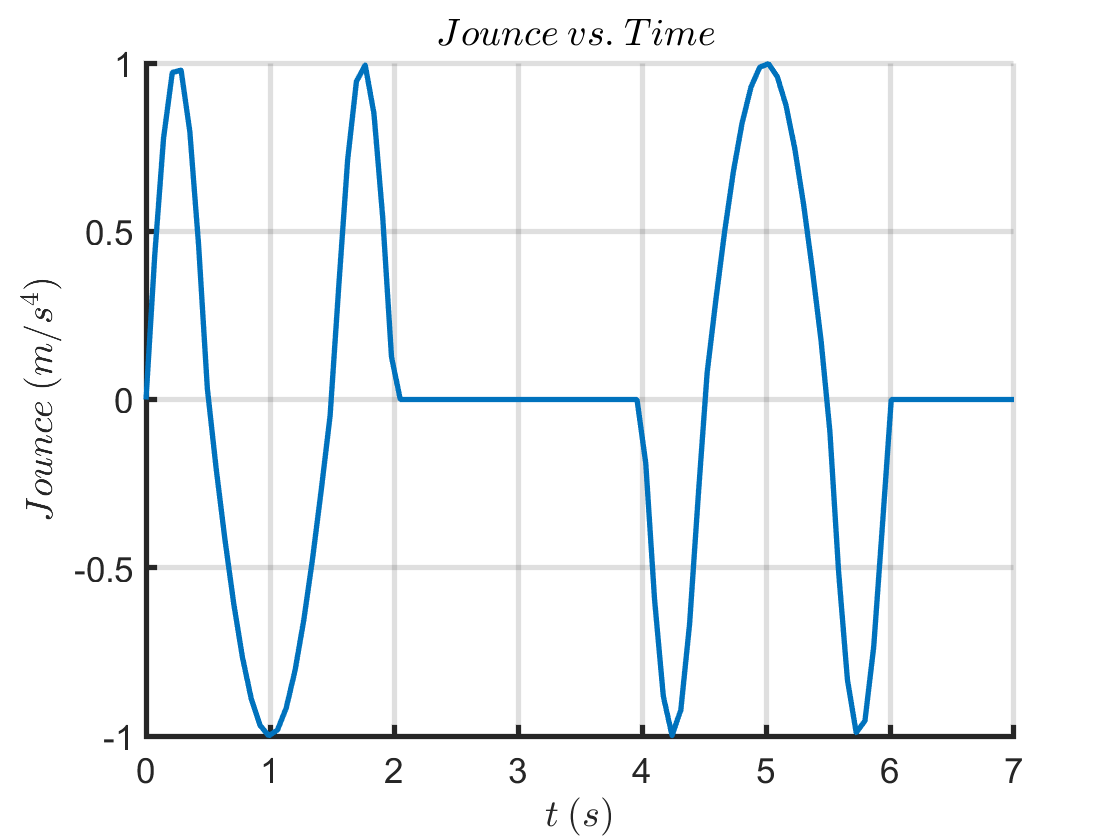

w = warning ('off','all');
% Plottitng
figure,
hold on
plot(t_range,val(1,:), 'Linewidth',2)

hold off
title('$ Jounce\:vs.\:Time\:$','Interpreter','latex');
ylabel('$Jounce\:(m/{s^4})$','Interpreter','latex');
xlabel('$t\:(s)$','Interpreter','latex');
grid on
set(gca,'FontSize',13,'linewidth',2);

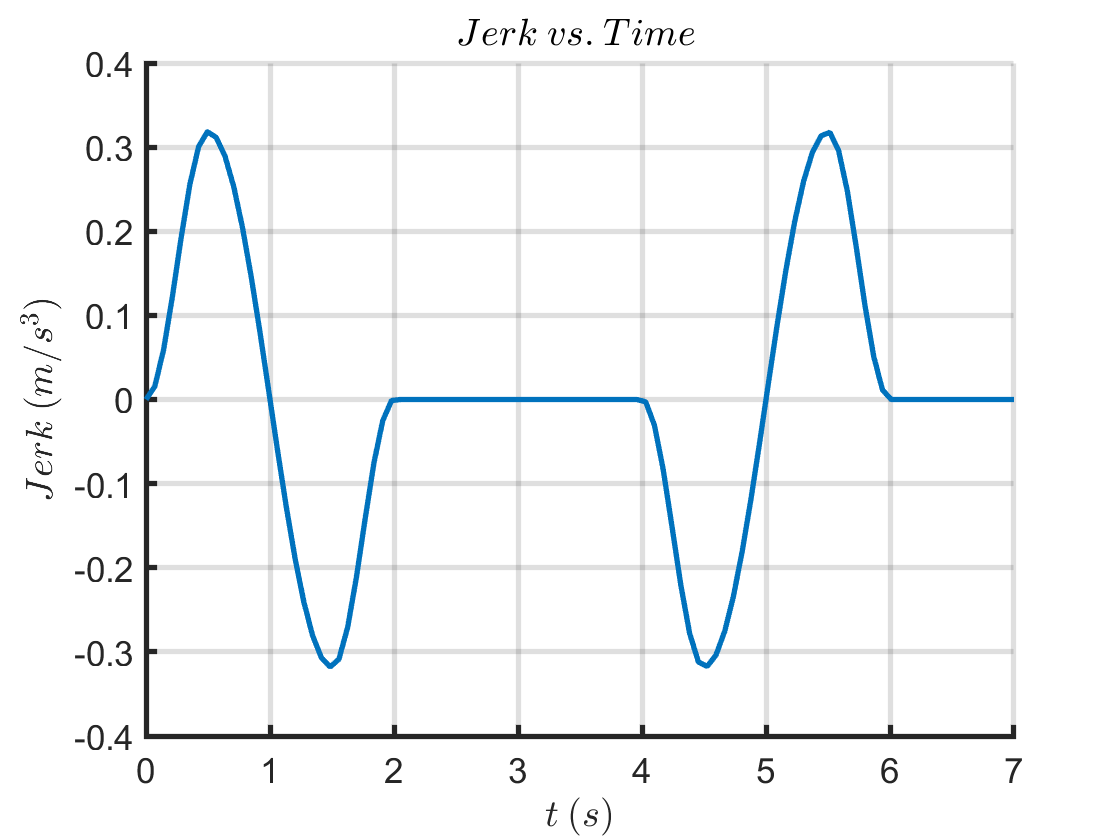

w = warning ('off','all');
% Plottitng
figure,
hold on
plot(t_range,val(2,:), 'Linewidth',2)

hold off
title('$ Jerk\:vs.\:Time\:$','Interpreter','latex');
ylabel('$Jerk\:(m/{s^3})$','Interpreter','latex');
xlabel('$t\:(s)$','Interpreter','latex');
grid on
set(gca,'FontSize',13,'linewidth',2);

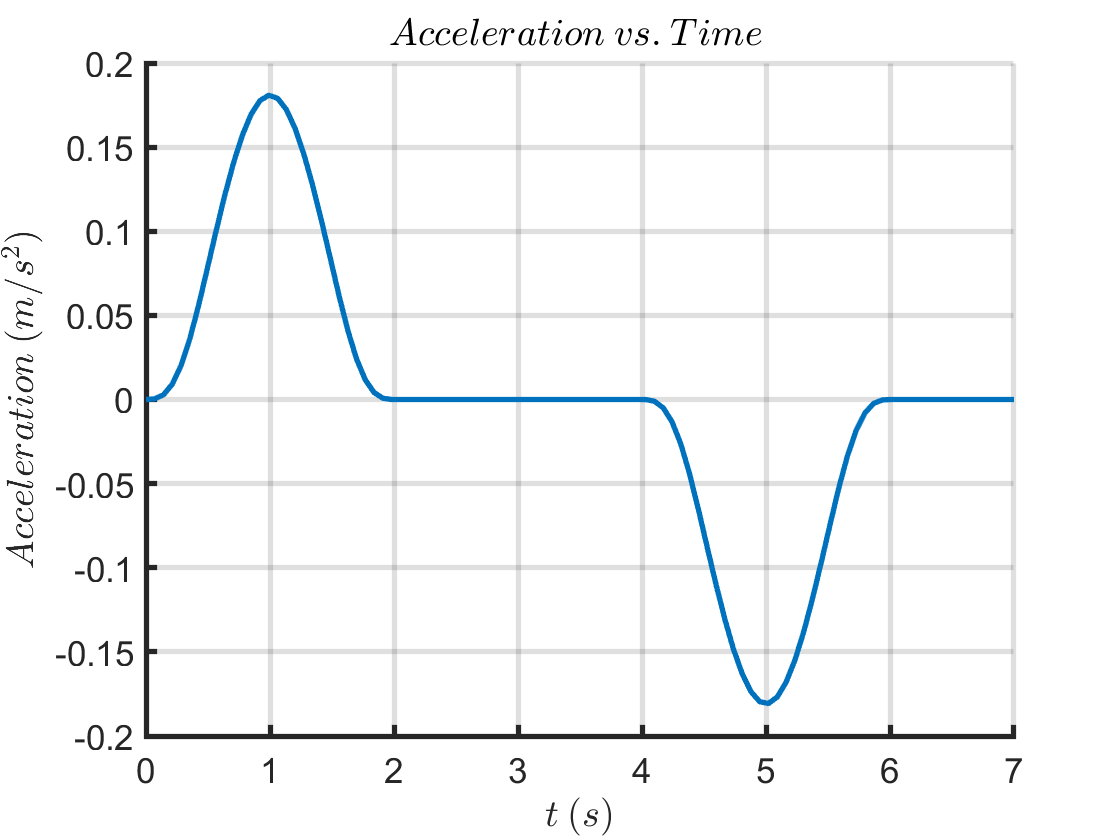

w = warning ('off','all');
% Plottitng
figure,
hold on
plot(t_range,val(3,:), 'Linewidth',2)

hold off
title('$ Acceleration\:vs.\:Time\:$','Interpreter','latex');
ylabel('$Acceleration\:(m/{s^2})$','Interpreter','latex');
xlabel('$t\:(s)$','Interpreter','latex');
grid on
set(gca,'FontSize',13,'linewidth',2);

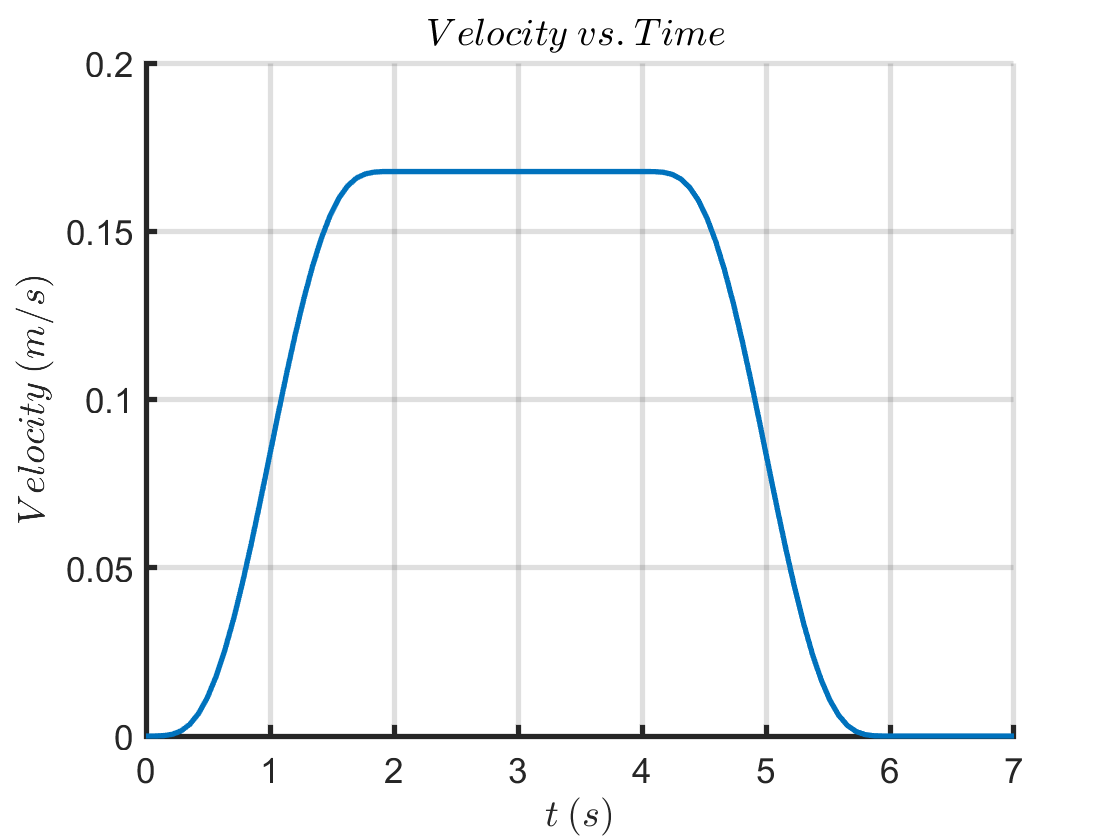

w = warning ('off','all');
% Plottitng
figure,
hold on
plot(t_range,val(4,:), 'Linewidth',2)

hold off
title('$ Velocity\:vs.\:Time\:$','Interpreter','latex');
ylabel('$Velocity\:(m/{s})$','Interpreter','latex');
xlabel('$t\:(s)$','Interpreter','latex');
grid on
set(gca,'FontSize',13,'linewidth',2);

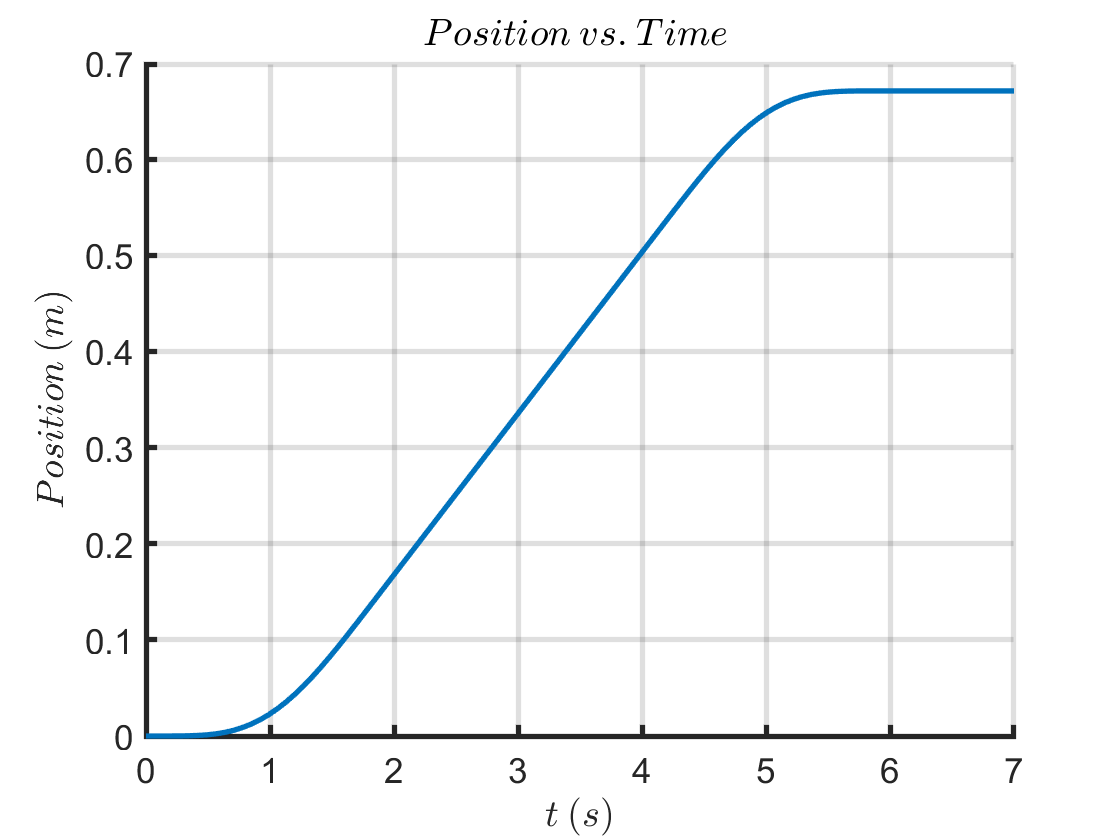

w = warning ('off','all');
% Plottitng
figure,
hold on
plot(t_range,val(5,:), 'Linewidth',2)

hold off
title('$ Position\:vs.\:Time\:$','Interpreter','latex');
ylabel('$Position\:(m)$','Interpreter','latex');
xlabel('$t\:(s)$','Interpreter','latex');
grid on
set(gca,'FontSize',13,'linewidth',2);

function func= Csolve(func,a,b,t,c, A,B,T,strt)
    y=eval(simplify(subs(func,[a,b,t],[A,B,T])));
    if isnan(y)
        func=eval(simplify(subs(func,[c],[strt])));
    elseif y==c
        func=eval(simplify(subs(func,[c],[strt])));
    else
        func_c=solve(y==strt,c);
        func=eval(simplify(subs(func,[c],[func_c])));
    end
end